frame1 = imread("Rt9Frame1.png");
frame2 = imread("Rt9Frame2.png");

of = opticalFlowFarneback;

estimateFlow(of, im2gray(frame1));
flow = estimateFlow(of, im2gray(frame2));

threshold = 1;

mask = (flow.Magnitude > 1);

mask = bwareafilt(mask, [500, Inf]);

se = strel("disk", 20, 0);
mask = imclose(mask, se);

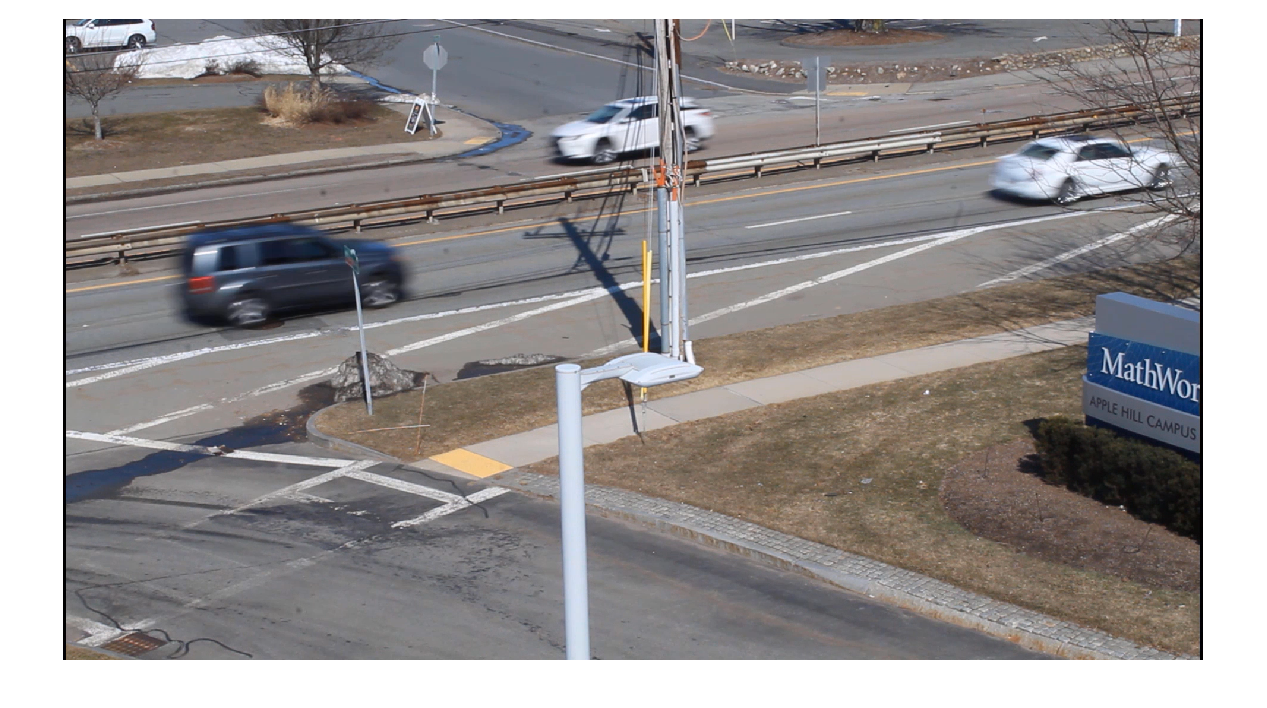

imshow(frame2)

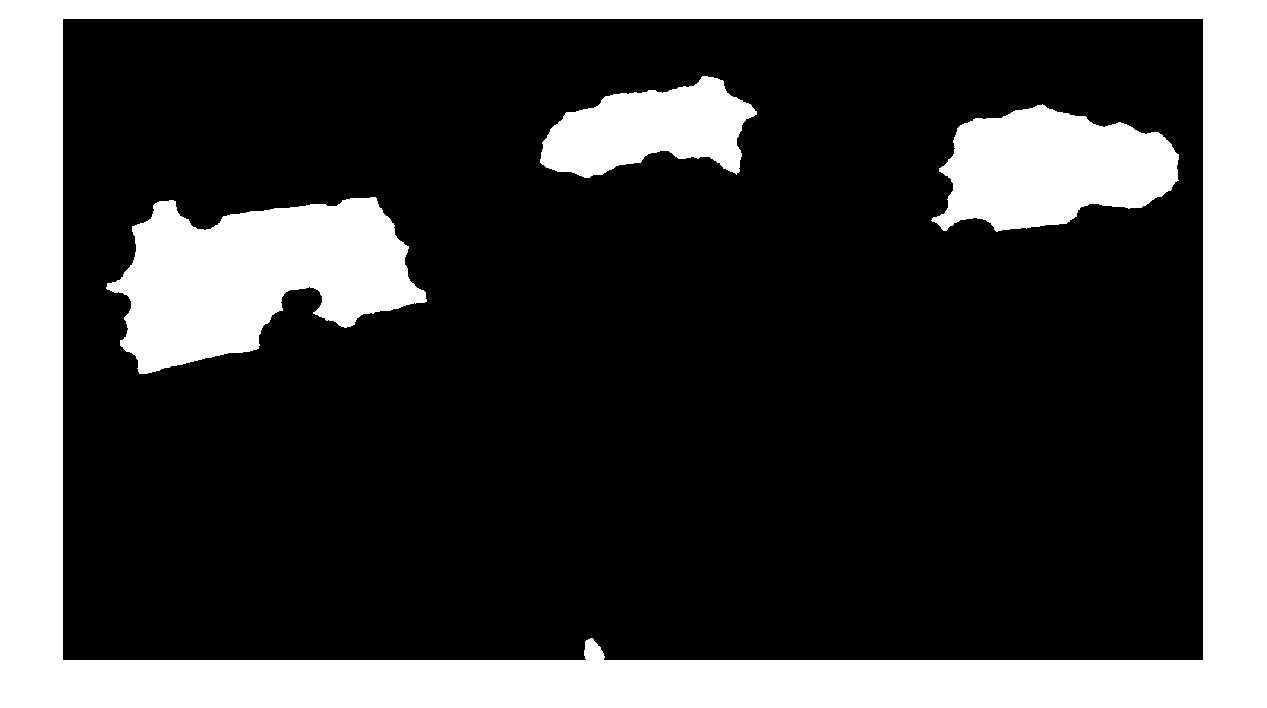

imshow(mask)

movObjs = regionprops("table",mask,flow.Vx,["MeanIntensity","BoundingBox", "Centroid"]);

leftVx = [];
rightVx = [];
i = 1;
numCarsLeft = 0;
numCarsRight = 0;

while i <= height(movObjs)
    avgVx = movObjs.MeanIntensity(i);
    if abs(avgVx) > 3
        if sign(avgVx) == -1
            leftVx = [leftVx; avgVx];
            numCarsLeft = numCarsLeft + 1;
        else
            rightVx = [rightVx; avgVx];
            numCarsRight = numCarsRight + 1;
        end
    end
    i = i + 1;
end
   

% leftVx
% rightVx
% numCarsLeft
numCarsRight

numCarsRight = 2